# Anexo B1

## Preparação

clear

% Quantidades e dimensões
k = 100;
n = 2;
T = 1;

## Realização

x = zeros(k,n);
u = (zeros(k,n)+1);
F = [...
    1 T; ...
    0 1 ...
    ];
G = zeros(n);
TAU = [...
    T^2/2; ...
    T ...
    ];

## Observação

z = zeros(k,1);
H = [1 0];

## Ruídos

mu = [ 0 0 ];
q = 0.01;
r = 1;
rng(1);
w = randn(k, 1)*sqrt(q);
rng(2);
v = randn(k, 1)*sqrt(r);
Q = q;
R = r;

## Condições iniciais

x(1,:) = [0 10];
z(1,:) = (H*x(1,:)' + v(1,:)')';
p00 = [...
    r r/T; ...
    r/T 2*r/T^2 ...
    ];

## Inicialização dos vetores de estimação

x_priori = x;
x_posteriori = x;
P_posteriori = p00;      % P(0|0)

## Evolução, previsão e estimação do estado

for i = 2:k
    % Realização: o estado evolui para x_n
    x(i,:) = (F*x(i-1,:)' + G*u(i-1,:)' + TAU*w(i-1,:)')';
    
    % Estimação: estimamos x-_n com base em x+_n-1
    x_priori(i,:) = (F*x_posteriori(i-1,:)'+G*u(i-1,:)')';
    
    % Obtemos P-_n a partir de P+_n-1
    P_priori = F*P_posteriori*F'+TAU*Q*TAU';
    
    % Obtemos K_n a partir de P-_n
    K = P_priori*H'/(H*P_priori*H'+R);
    
    % Obtemos P+_n a partir de P-_n
    P_posteriori = (eye(n)-K*H)*P_priori;
    variancia(i,:) = [P_posteriori(1,1),P_posteriori(2,2)];

    % Observação: medimos z_n
    z(i,:) = (H*x(i,:)' + v(i,:)')';
    
    % Previsão (Filtro de Kalman): estimamos x+_n com base em x-_n, z_n e K_n 
    x_posteriori(i,:) = x_priori(i,:)+(K*(z(i,:)'-H*x_priori(i,:)'))';
    
end

## Plots

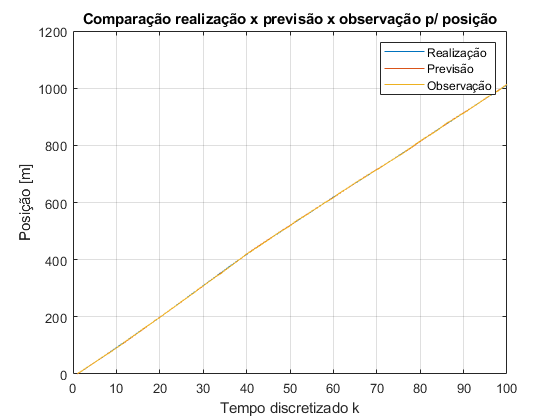

figure;
plot(1:k, x(:,1));
hold on;
plot(1:k, x_posteriori(:,1));
hold on;
plot(1:k, z(:,1));
grid on;
xlabel("Tempo discretizado k");
ylabel("Posição [m]");
legend("Realização", "Previsão", "Observação");
title("Comparação realização x previsão x observação p/ posição");

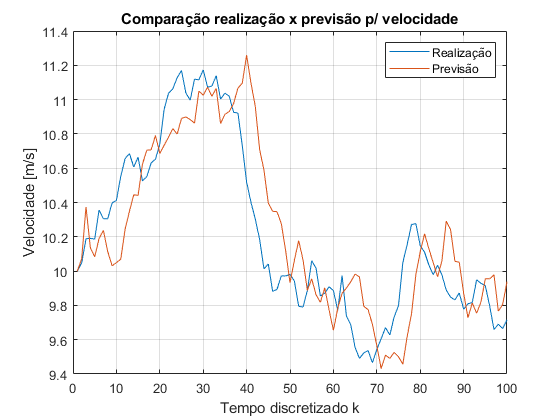


figure;
plot(1:k, x(:,2));
hold on;
plot(1:k, x_posteriori(:,2));
grid on;
xlabel("Tempo discretizado k");
ylabel("Velocidade [m/s]");
legend("Realização", "Previsão");
title("Comparação realização x previsão p/ velocidade");

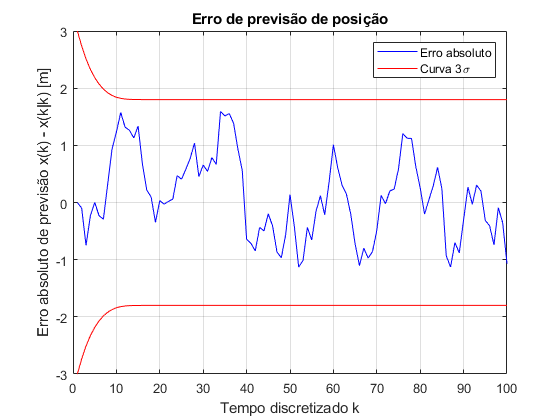


erro_medicao = x-x_posteriori;
variancia(1,:) = [p00(1,1),p00(2,2)];
figure
plot(1:k, erro_medicao(:,1), 'b');
hold on;
grid on;
plot(1:k, 3*sqrt(variancia(:,1)), 'r')
plot(1:k, -3*sqrt(variancia(:,1)), 'r')
title("Erro de previsão de posição");
xlabel("Tempo discretizado k");
ylabel("Erro absoluto de previsão x(k) - x(k|k) [m]");
legend("Erro absoluto", "Curva 3\sigma");

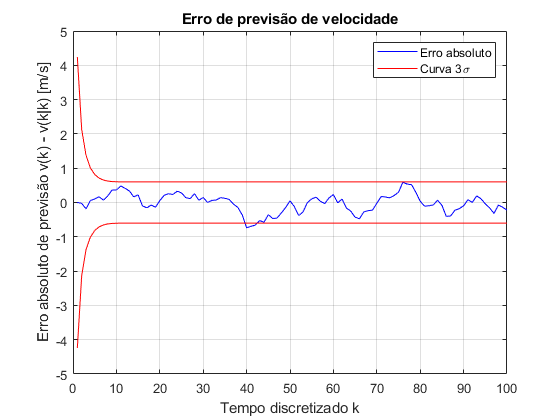


figure
plot(1:k, erro_medicao(:,2), 'b');
hold on;
grid on;
plot(1:k, 3*sqrt(variancia(:,2)),'r')
plot(1:k, -3*sqrt(variancia(:,2)),'r')
title("Erro de previsão de velocidade");
xlabel("Tempo discretizado k");
ylabel("Erro absoluto de previsão v(k) - v(k|k) [m/s]");
legend("Erro absoluto", "Curva 3\sigma");